# Assignment 8 

# **Development of optimal smoothing to increase the estimation accuracy**  

By 

Group 19 

Ahmed Baza, Skoltech, 2020

Ahmed Elgohary, Skoltech, 2020

Mohammed Sayed, Skoltech, 2020

Ziad Baraka, Skoltech, 2020

1. Generate a true trajectory $x_i$ of an object motion disturbed by normally distributed random acceleration

2. Generate measurements $z_i$ of the coordinate $x_i$

clc; clear

N=200;              % size of trajectory
x = zeros(N,1);     % real data for position
V = zeros(N,1);     % real data for velocity
a = zeros(N,1);     % noise
z = zeros(N,1);     % measurements
s_alpha = 0.2^2;    % sigma_w^2
s_eta = 20^2;

x(1) = 5;           % initial position
V(1) = 1;           % initial velocity
a(1) = normrnd(0,sqrt(s_eta));
z(1) = x(1) + a(1);
T = 1;              % time step

for i = 2:N
    a(i) = normrnd(0,sqrt(s_alpha));
    x(i) = x(i-1) + V(i-1)*T + a(i)*T^2 /2; 
    V(i) = V(i-1) + a(i)*T;  
    z(i) = x(i) + normrnd(0,sqrt(s_eta));
    
    
end

3. Present the system at state space taking into account that only measurements of coordinate $x_{i\;}$are availabe 

4. Develop Kalman filter algorithm to estimate state vector $X_i$ (extrapolation and filtration)

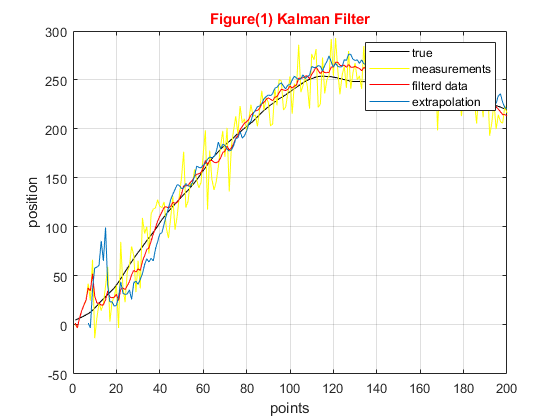

phi = [1 T;0 1];    % transition matrix that relates Xi to Xi-1
G = [T^2/2;T];      % input matrix, that determines how random acceleration affects state vector
H = [1 0];          % observation matrix
Q = G*G'*s_alpha;   % covariance matrix of state noise
K = zeros(N,2);     %  array to save filter gain


I = eye(2);
R = s_eta;          % covariance matrix of measurements noise

X = zeros(N,2);     % state vector, that describes full state of the system
x_extrapolated = zeros(N-6,1);
X(1,:)=[2,0];                    % Initial filtered estimate
P_filteration = [10000 0; 0 10000];          % Initial filtration error covariance matrix
P_value = zeros(N,1);            % array to save the caculation error 
K(1,:) = (P_filteration*H'*(H*P_filteration*H'+R)^-1)';  % initial value of filter gain

m = 7;                  % extrapolation steps
P_filteration_cell = cell(N,1);     % cell to save the P_filteration matrices
P_prediction_cell = cell(N,1);     % cell to save the P_prediction matrices
P_filteration_cell{1} = P_filteration;

% kalman filter
for i = 2:N
    % prediction(extrapolation)
        X_predicted = phi * X(i-1,:)';      % Prediction of state vector at time i using i − 1 measurements
        P_prediction = phi*P_filteration*phi' + Q;                 % Prediction error covariance matrix
    % filteration
        X(i,:) = X_predicted + K(i-1,:)'*(z(i)- H*X_predicted);     % Improved estimate by incorporating a new measurement
        K_updated = P_prediction*H'*(H*P_prediction*H'+R)^-1;     % Filter gain, weight of residual
        P_filteration = (I - K_updated*H)*P_prediction;            % Filtration error covariance matrix
    % extrapolation
        if i >= m
            x1 = phi^(m-1) * X(i-m+1,:)';
            x_extrapolated(i-m+1)=x1(1);
        end
    % save values to be used in the smoothing step
        P_filteration_cell{i} = P_filteration; 
        P_prediction_cell{i} = P_prediction; 
    
P_value(i)=sqrt(P_filteration(1,1));        
K(i,:) = K_updated;

end

figure(1)
plot(x,'k'); hold on
plot(z,'y'); hold on
plot(X(:,1),'r'); hold on
plot(7:200,x_extrapolated)
legend('true','measurements','filterd data','extrapolation')
title ('Figure(1) Kalman Filter','color','r'); xlabel('points'); ylabel('position')
grid on

Comment:

In figure(1) above, the true trajectory, the measurements, the Kalman filter estimation and extapolation with 7 steps ahead are graphed against each other. It can be seen that the estimation values are kind of following the trajectory with some disturbances. And plotting the filter with different random trajectories leads to the same results. Also,  the extrapolation follows the behavior of the estimation more, which makes sense as it’s based on it. Moreover,  it’s more noisy at the beginning of the trajectory so it cannot be trusted at this region as an estimation of the true model, and lastly we can predict that both the error of filter estimation and the extrapolation will have the same behavior with close values.

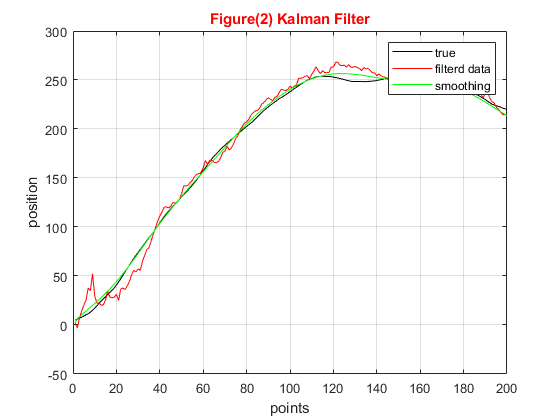

 % backward sommothing
        X_smoothed = zeros(N,2);
        P_smoothing_value_X = zeros(N-1,1);
        P_smoothing_value_V = zeros(N-1,1);
        P_filteration_cell{1} = P_filteration;
        X_smoothed(N,:) = X(N,:);
        P_smoothing = P_filteration_cell{N};
        
        for i =  N-1:-1:1
            A = P_filteration_cell{i}*phi'/P_prediction_cell{i+1};
            X_smoothed(i,:) = X(i,:)' + A*(X_smoothed(i+1,:)' - phi*X(i,:)');
            P_smoothing = P_filteration_cell{i}+A*(P_smoothing -P_prediction_cell{i+1})*A';
            P_smoothing_value_X(i) = sqrt(P_smoothing(1,1));
            P_smoothing_value_V(i) = sqrt(P_smoothing(2,2));
        end

figure(2)
plot(x,'k'); hold on
%plot(z,'y'); hold on
plot(X(:,1),'r'); hold on
%plot(7:200,x_extrapolated); hold on
plot(X_smoothed(:,1),'g')
%legend('true','measurements','filterd data','extrapolation','smoothing')
legend('true','filterd data','smoothing')
title ('Figure(2) Kalman Filter','color','r'); xlabel('points'); ylabel('position')
grid on

**comment:** 

 Compairng the backward smoothed results to the kalman fileter output. the error after smoothing is very small and the filter can capture the dynamics of the system to a great extent. the kalman filter results still have good aproximation.    

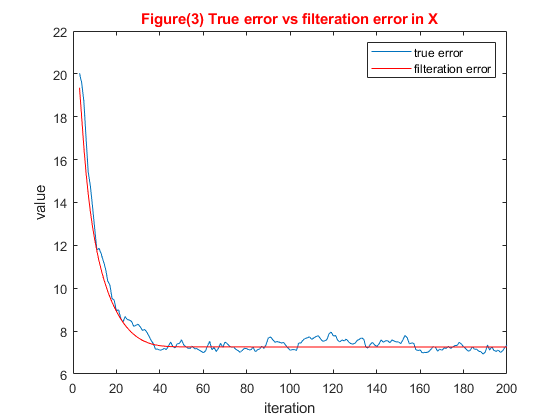

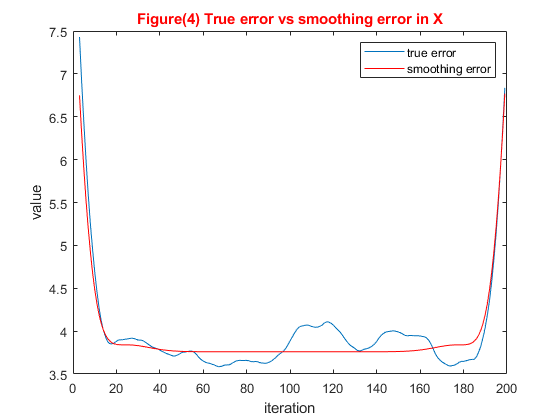

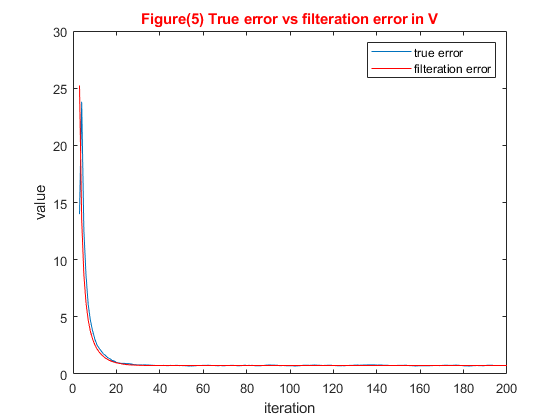

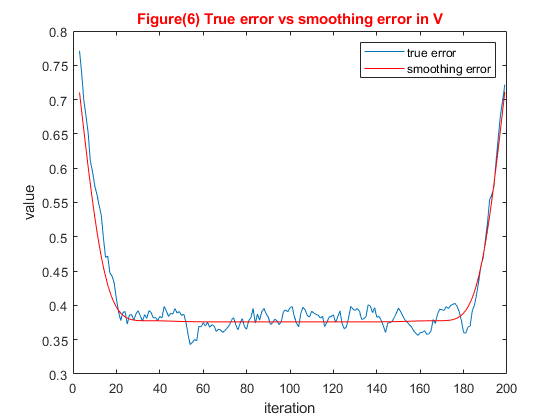

clc; clear; close all;
% code for M=500 runs
M_runs_smoothing(500)

Comment: 

# Learning Log: